force_curve = open_JPK("./raw/force-save-0100.jpk-force")

force_curve = 1×5 struct array with fields:
    Channel_name
    Encoded
    nominal
    calibrated
    distance
    force
    extend
    retract
    pause


sensorheight = force_curve(3).retract.Data_Raw;%height channel
deflection = force_curve(5).retract.Data_Raw;

[sensorheight_sorted, idx] = sort(sensorheight);
deflection_sorted = deflection(idx);

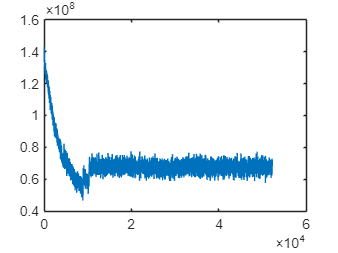

plot(deflection)

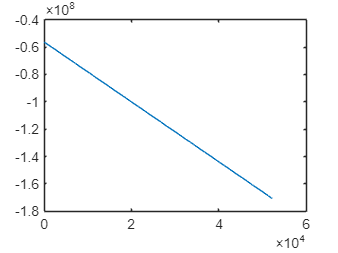

plot(sensorheight)

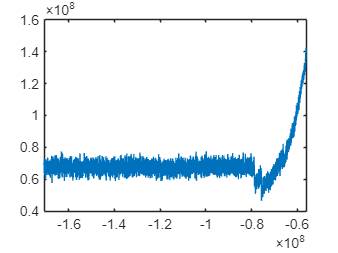

plot(sensorheight,deflection)

%plot(sensorheight_sorted)
%plot(deflection_sorted)
%scatter(sensorheight_sorted,deflection_sorted)

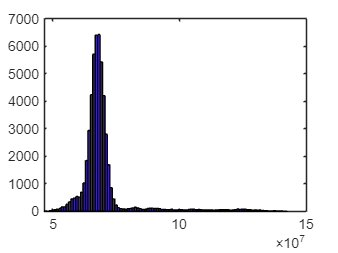

hist(deflection, 100)

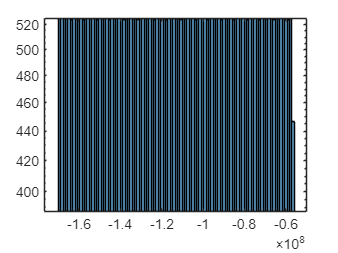

histogram(sensorheight_sorted,100)
set(gca, 'YScale', 'log');

names = 3×1 cell array
    {'Data_Raw'    }
    {'Data_Encoded'}
    {'Data_nominal'}


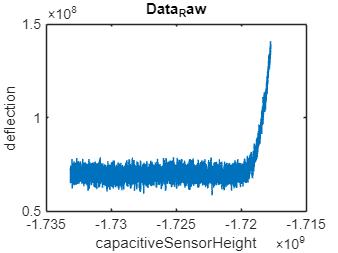

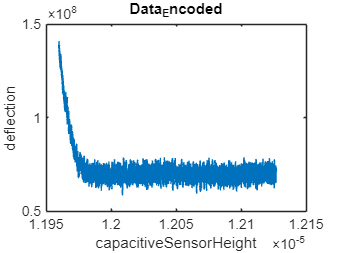

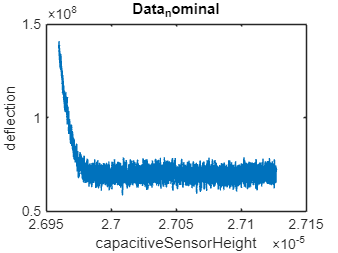

names = 4×1 cell array
    {'Data_Raw'       }
    {'Data_Encoded'   }
    {'Data_nominal'   }
    {'Data_calibrated'}


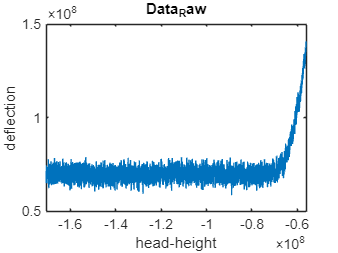

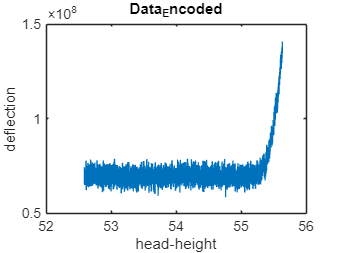

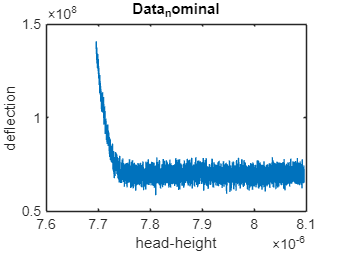

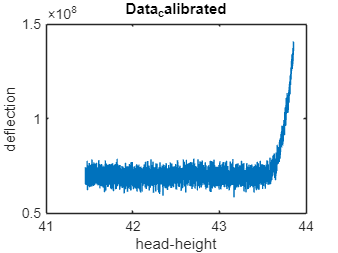

names = 4×1 cell array
    {'Data_Raw'       }
    {'Data_Encoded'   }
    {'Data_nominal'   }
    {'Data_calibrated'}


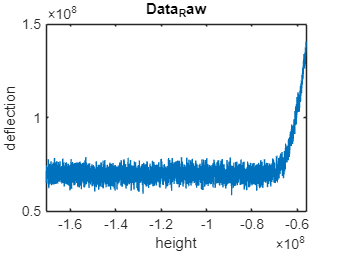

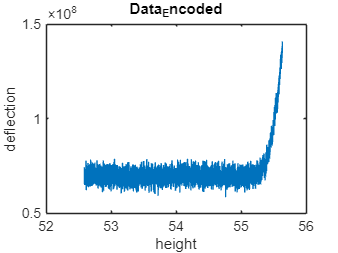

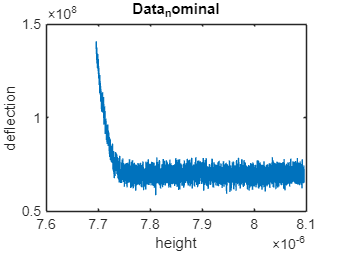

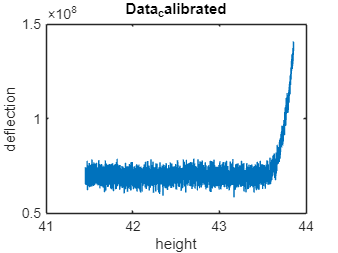

names = 3×1 cell array
    {'Data_Raw'    }
    {'Data_Encoded'}
    {'Data_nominal'}


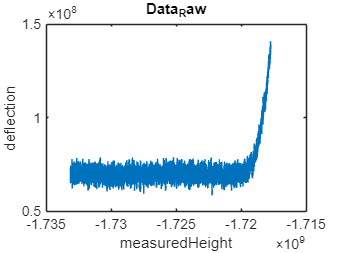

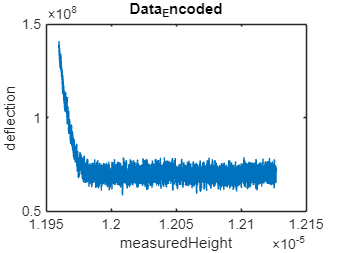

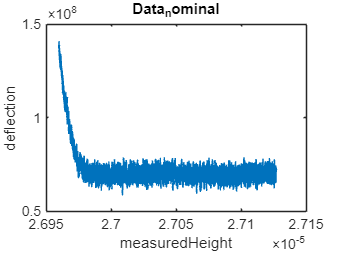

names = 4×1 cell array
    {'Data_Raw'     }
    {'Data_Encoded' }
    {'Data_distance'}
    {'Data_force'   }


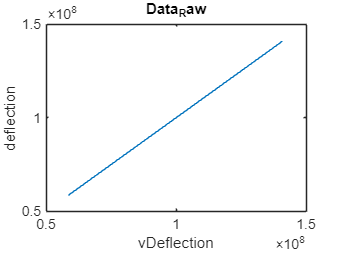

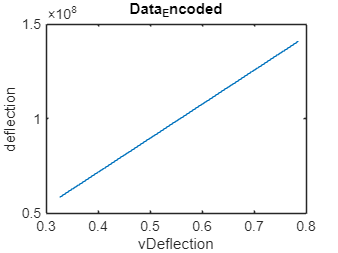

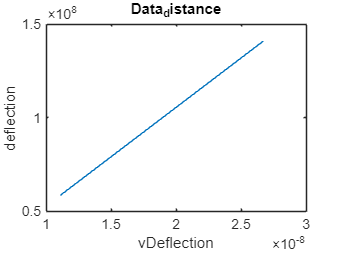

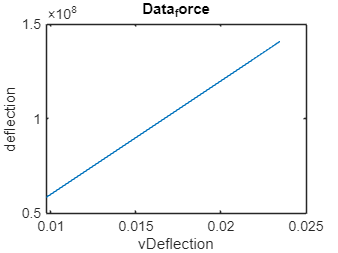

dataStruct = force_curve;
channelNames = {'capacitiveSensorHeight', 'head-height', 'height', 'measuredHeight', 'vDeflection'};
numChannels = length(channelNames);
deflection_extend = force_curve(5).extend.Data_Raw;
deflection_retract = force_curve(5).retract.Data_Raw;
for i = 1:5
    extend = force_curve(i).extend;
    retract = force_curve(i).retract;
    names = fieldnames(extend)
    numFields = length(names);
    for j=1:numFields
        name = names{j};
        sensorheight=extend.(name);
        [sensorheight_sorted, idx] = sort(sensorheight);
        deflection_extend_sorted = deflection_extend(idx);
        figure;
        %scatter(sensorheight_sorted, deflection_extend_sorted)
        plot(sensorheight, deflection_extend)
        title(name)
        xlabel(force_curve(i).Channel_name)
        ylabel("deflection")
    end
   
end